# Region Segmentation

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

An introduction to region-based image segmentation techniques. 

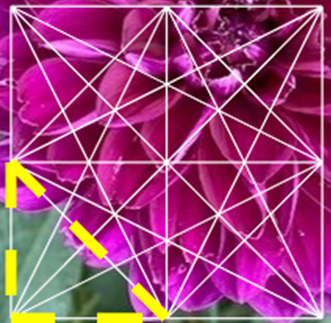

An overview of region segmentation techniques, including histogram, k-means clustering, and graph-cut algorithms.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

  **Pro-tip**. Review [Machine Learning Methods: Clustering ](https://www.mathworks.com/matlabcentral/fileexchange/135381-machine-learning-methods-clustering)to learn how clustering works and to learn the fundamentals of k-means clustering.

## Region Segmentation

Region-based segmentation is an image processing technique that groups pixels into regions based on specific criteria such as color, intensity, or texture. The primary goal is to divide an image into meaningful segments where pixels within the same region exhibit similar properties. For instance, all pixels within a region may share similar colors in a color image, forming a cohesive segment.

In an MRI scan of the brain, region-based segmentation can help distinguish between different tissue types by grouping pixels with similar intensity values. This segmentation is crucial for diagnosing conditions, planning surgeries, and monitoring treatment progress.

## Histogram-Based Segmentation

### Histogram-Based: Theory

**Histogram-based segmentation** is a technique used in image processing to partition or segment an image into different regions based on the intensity values of its pixels. This method involves creating a histogram of the pixel intensities and identifying peaks and valleys in the histogram to determine thresholds. These thresholds are then used to segment the image into distinct regions. The main advantage of histogram-based segmentation is its simplicity and efficiency, making it suitable for images with well-defined intensity distributions. 

  **Try**. View the toy image and its corresponding histogram by pressing the button below.

 
Toy = imread("Toy.jpg");
figure
imshow(Toy)
title("Toy Image")
figure
ToyG = im2gray(Toy);
HistDisp(ToyG)
title("Histogram of Toy Image") % Add a title to the histogram

We can view pixel intensity ranges for the 3 sets of pixel ranges in our image. 

  **Try**. Display the histogram for each specified range within the pixel regions of the toy image.

% Display histogram of toy image with intensity range 100 to 150
if ~exist("ToyG","var")
    Toy = imread("Toy.jpg");
    ToyG = im2gray(Toy);
    ToyG = ToyG(:);
end

figure
Range = "Select"; % Non-default settings: "[0,50]","[100,150]" and "[200,255]"
if ~strcmp(Range,"Select")
    DispHist(Range,ToyG);
    title("Histogram of Toy Image for " +  Range + " Pixel Range") % Add a title to the histogram
else
    disp("Select a valid option.") %#ok<*UNRCH>
end

 **Exercise 1. **Which bin range is associated with the square object in the toy image?

**Solution:**

CheckAnswer("Exercise1","Select")   % Non-default settings: "[0,50]","[100,150]" and "[200,255]"

### Histogram-Based: Application

Though histogram-based segmentation is easy for well-defined regions, it is more difficult for images with overlapping intensity ranges or that require more complex segmentation criteria. What if the image is not quite as simple? If we increase the complexity of our toy image by adding noise, then the histogram is more spread out. Can you distinguish between the regions of the histogram now? 

 
if ~exist("ToyG","Var")
    ToyG = imread("Toy.jpg");
    ToyG = im2gray(ToyG);
end

figure
ToyNoise = imnoise(ToyG,"gaussian",0.3);
imshow(ToyNoise)
title("Noisy Toy Image")

figure
HistDisp(ToyNoise);
title("Histogram of Noisy Toy Image");

  **Try**. Display the histogram for each specified range within the pixel regions of the toy image.

if ~exist("ToyNoise","Var")
    ToyG = imread("Toy.jpg");
    ToyG = im2gray(ToyG);
    ToyNoise = imnoise(ToyG,"gaussian",0.3);
    ToyNoise = ToyNoise(:);
end

figure
RangeN = "Select"; % Non-default options include: Non-default settings: "[0,50]","[100,150]" and "[200,255]"

if ~strcmp(RangeN,"Select")
    DispHist(RangeN,ToyNoise);
    title("Histogram of Noisy Toy Image for " + RangeN + " Pixel Range");
else
    warning("Select a valid option.")
end

## K-Means Clustering

### K-Means Clustering: Theory

We need to perform clustering to identify "centers or centroids" representative of various colors or intensities in an image. The **k-means clustering** algorithm accepts a user-chosen value of *k*, the number of clusters. Initially, it randomly selects the centroid locations for each cluster. Then, it assigns each data point to the nearest cluster based on the sum of squared distances (SSD) from the centroids. Due to the random selection of centroids, cluster assignments can vary.

The best cluster centers minimize the SSD between all points and their nearest cluster center, *ci*, using the equation:


$$
SSD = \sum_\text{cluster i} \sum_{x \in \text{cluster i}} (x - c_i)^2$$


Manually determining optimal cluster centers is challenging because we don't know which pixels belong together. **K-means clustering** automates this process by iteratively refining the centroids to minimize the SSD, effectively grouping similar pixels. This is crucial for tasks like image segmentation, where accurately identifying regions with similar colors or intensities is essential.

  **Try**. Perform k-means clustering to segment the noisy toy image. Select the number of clusters, *k*.

 
fig = figure;
fig.Units = "pixels";
screensize = get(0,"ScreenSize");
gcf.Position = screensize;

tiledlayout(1,2)
nexttile(1)
ToyK = imread("Toy.jpg"); % Load image
ImgKmeans = imnoise(ToyK,"gaussian",0.3); %#ok<*NASGU>
ImgKmeans = rgb2lightness(ImgKmeans);

imshow(ImgKmeans,[])
title("Original Image")
% Convert to double for processing
ImgDouble = im2double(ImgKmeans);

K = 4;
nexttile(2)
[clusterIndices,score] = ScatKmeans(ImgDouble,K);

#### Validation with Silhouette Plots

A silhouette graph is a useful tool for assessing the quality of clusters created by the **k-means clustering** algorithm. Silhouette graphs work by calculating a silhouette score for each data point, which ranges from -1 to 1, with higher scores indicating better clustering. The graph plots these scores on the x-axis and lists the data points by cluster on the y-axis. High silhouette scores indicate well-clustered points, while low or negative scores suggest points that might be incorrectly clustered or positioned between clusters. The width of each cluster in the graph represents the number of points within that cluster. If many points have low or negative scores, it may be necessary to adjust the number of clusters and re-run the k-means clustering algorithm.

Key criteria for good silhouette plots include:

- ***Silhouette Scores***: High average scores indicate well-defined clusters.

- ***Separation***: Clear gaps between clusters, showing minimal overlap.

- ***Width***: Uniform widths within each cluster, representing the number of points.

  **Try**. Adjust the k-value in the k-means algorithm to achieve the optimal silhouette graph. Use the key criteria for good silhouette plots to adjust your k-value.

K = 4;

% Create silhouette plot to compare the results of cluster data
figure
if exist("ImgDouble","var")
    tiledlayout(1,2)
    nexttile(1)
    [clusterIndices,score] = ScatKmeans(ImgDouble,K);

    nexttile(2)
    silhouette(score,clusterIndices,"cityblock");
    title("Silhouette Plot for K-means Clustering");
    xlabel("Silhouette Value")
    ylabel("Cluster Index")
    AvgSilVal = mean(clusterIndices);
    AvgSilVal = round(AvgSilVal,3,"significant");
    disp("The average silhouette value is: " + AvgSilVal)

    % Scale figure to screen size
    fig = gcf; % Get current figure
    screensize = get(0,"ScreenSize"); % Get screen size
    fig.Position = screensize; % Set figure position to full screen
else
    warning("Perform k-means clustering above.")
end

 **Exercise 2. **How many clusters should you use to segment the noisy toy image?

**Solution:**

CheckAnswer("Exercise2","Select") % Non-default options include: "Two", "Three", "Four", and "Five"

### K-Means Clustering: Applications

We've been working with grayscale images, but most of our images are in the RGB color space. RGB does not match human vision well. Using the L*a*b* color space helps us see color differences better because it aligns more closely with human vision. L*a*b* separates lightness (L*) from color (a* and b*), allowing us to adjust brightness and color independently.

To segment by color, we convert the image to L*a*b* and use k-means clustering to see the color-based groups. Each group represents similar pixels.

  **Try**. Perform k-means clustering on an image.

- *Select an image on which to perform k-means clustering.*

- *(Optional) Check the box to preview the image.*

- *Select the number of clusters, k, to perform k-means clustering on your chosen image.*

- *Press the button to perform k-means clustering.*

ImageR = "Select"; % Non-default options include: "Beach.jpg", "Glacier.jpg" and, "Scene.jpg"
if ~strcmp(ImageR,"Select")
    PrevImg = false;
    k = 3;
    [PixSamp,idx] = PlotKClust(ImageR,k,PrevImg);
     
else
    warning("Select a valid option.")
    return
end

#### Validation of K-means Clustering

Remember the key criteria for good silhouette plots. These criteria suggest that the clustering structure is strong and that the chosen *k* effectively captures the natural grouping in the data. If the silhouette plot meets these criteria, it means you have likely chosen a value of *k* that is close to the correct number of clusters for your data.

  **Try**. Evaluate your choice of k used to perform k-means clustering on your chosen image above.

if exist("ImageR","var")
    k = 3;
    [PixSamp,idx] = PlotKClust(ImageR,k,false);
     

    % Create silhouette graph for the clustering (only if clusters are valid)
    if numel(unique(idx)) > 1
        figure
        silhouette(PixSamp,idx,"cityblock");
        title("Silhouette Plot for K-means Clustering");
        xlabel("Silhouette Value")
        ylabel("Cluster Index")
    else
        warning("Silhouette plot cannot be generated with only one cluster.");
    end
    AvgSilValB = mean(idx);
    AvgSilValB = round(AvgSilValB,3,"significant");
    disp("The average silhouette value is: " + AvgSilValB)
else
    warning("Select an image above.")
end


## Graph-Cut Segmentation

**K-means clustering** is ideal for partitioning data into a predefined number of clusters based on feature similarity. It's commonly used in applications where data can be represented in a feature space, such as color-based image segmentation. However, when the goal is to partition an image into regions with distinct boundaries for precise object delineation, such as segmenting an object from the background, it is best to use **graph-cut segmentation**.

In **graph-cut segmentation**, an image is represented as a graph. Each pixel in an image can be treated as a node in a graph. Nodes are connected by edges, which can be weighted to indicate the strength of the connection between nodes. These weights measure the similarity between connected pixels.

The goal is to partition the graph into subgraphs by cutting the edges. Pixels that resemble each other should be clustered in the same segment, whereas pixels that differ should be assigned to separate segments. The outcome of the graph cut is a binary segmentation of the image. Classifying each pixel as either foreground or background based on the cut.

The steps of graph-cut segmentation are:

- *Draw the nodes*

- *Draw the edges*

- *Create subgraph 1 of similar edges*

- *Create subgraph 2 of similar edges*

- *Create final graph-cut segmentation*

** Demonstration**. Visualize the graph-cut segmentation process on a sample image.  

 
Img = "Flowerff.jpg";
GrphImg = flipud(imrotate(imread(Img),270));
[x,y,G,Edges] = GrphCut(GrphImg);

% Check if StepCount exists in the base workspace
if evalin("base", "exist('StepCount','var')")
    StepCount = evalin("base","StepCount");
else
    StepCount = 0;
end

if StepCount == 2
    % Plot all edges in a single call
    X = [x(Edges(:,1))'; x(Edges(:,2))'];
    Y = [y(Edges(:,1))'; y(Edges(:,2))'];
    line(X,Y,Color="white",LineWidth=2);
    title("2. Draw Edges");
    StepCount = StepCount + 1;

elseif StepCount == 3
    % Draw all base edges faintly (single call with NaNs)
    allX = [x(Edges(:,1))';x(Edges(:,2))';nan(1,size(Edges,1))];
    allY = [y(Edges(:,1))'; y(Edges(:,2))';nan(1, size(Edges,1))];
    line(allX(:),allY(:),Color=[1 1 1 0.3],LineWidth=0.5); % RGBA white with alpha

    % Selected highlighted edges
    selectedEdges = [9,18,12];
    he = Edges(selectedEdges,:);

    % Build NaN-separated vectors for each edge
    Xh = [x(he(:,1))';x(he(:,2))';nan(1,size(he,1))];
    Yh = [y(he(:,1))';y(he(:,2))';nan(1,size(he,1))];

    % Highlight with color
    line(Xh(:),Yh(:),LineStyle="--",LineWidth=3,Color="yellow");

    title("3. Create Subgraph 1 of Similar Edges");
    StepCount = StepCount + 1;


elseif StepCount == 4
    % Base edges again (low opacity look) — batch render
    Xall = [x(Edges(:,1))';x(Edges(:,2))';nan(1,size(Edges,1))];
    Yall = [y(Edges(:,1))';y(Edges(:,2))';nan(1,size(Edges,1))];
    line(Xall(:),Yall(:),Color=[1 1 1 0.3],LineWidth=0.5);

    % Subgraph 2 edges — batch render
    selectedEdgesB = [1,3,12,33,36,34,24];
    EdgesB = Edges(selectedEdgesB,:);
    Xb = [x(EdgesB(:,1))';x(EdgesB(:,2))';nan(1,size(EdgesB,1))];
    Yb = [y(EdgesB(:,1))';y(EdgesB(:,2))';nan(1,size(EdgesB,1))];

    % Batch draw highlighted subgraph edges
    line(Xb(:),Yb(:),Color="cyan",LineWidth=3);

    title("4. Create Subgraph 2 of Similar Edges");
    StepCount = StepCount + 1;

elseif StepCount >= 5
    % Re-plot Subgraph 1 (yellow dashed)
    selectedEdgesA = [9,18,12];
    EdgesA = Edges(selectedEdgesA,:);
    Xa = [x(EdgesA(:,1))';x(EdgesA(:,2))';nan(1,size(EdgesA,1))];
    Ya = [y(EdgesA(:,1))'; y(EdgesA(:,2))';nan(1,size(EdgesA,1))];
    line(Xa(:),Ya(:),LineWidth=3,LineStyle="--",Color="yellow");

    % Re-plot Subgraph 2 (cyan solid)
    selectedEdgesB = [1,3,12,33,36,34,24];
    EdgesB = Edges(selectedEdgesB,:);
    Xb = [x(EdgesB(:,1))';x(EdgesB(:,2))';nan(1,size(EdgesB,1))];
    Yb = [y(EdgesB(:,1))';y(EdgesB(:,2))';nan(1,size(EdgesB,1))];
    line(Xb(:),Yb(:),LineWidth=2,LineStyle="-",Color="cyan");

    title("5. Create final graph-cut segmentation");
    evalin("base", "clear StepCount");
    disp("You reached the final step. To try again, continue to press the button to step through the graph-cut visualization.");

else
    StepCount = 1;
    scatter(x,y,50,'white','filled');
    text(x-25,y,string(1:numel(x)),Color="yellow",FontWeight="bold",HorizontalAlignment="left",VerticalAlignment="middle");
    title("1. Draw Nodes");
    StepCount = StepCount + 1;
end

** Demonstration**. Use graph-cut segmentation to segment the flower from the background.

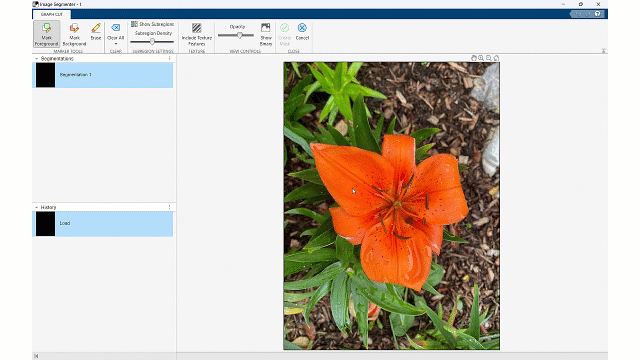

  **Try**. Use graph-cut segmentation to segment the objects (building, glacier, and path) from their respective backgrounds.

- *Load image in Image Segmenter App.*

- *Select the Graph-Cut icon from the Segmentation Tools toolstrip.*

- *Mark a foreground object by drawing inside the object. *

- *Mark a background object by drawing in the background around the object.*

- *Select Show Binary to display your binary segmented image.*

GraphImg = "Select"; % Non-default options include: "Bldg.jpg", "Path.jpg" and "Glacier.jpg"
if ~strcmp(GraphImg,"Select")
    GraphImg = imread(GraphImg);
    imageSegmenter(GraphImg)
else
    warning("Select a valid option.")
end

 **Exercise 3. **If you had to segment the cloud in the image below, which technique would you use?

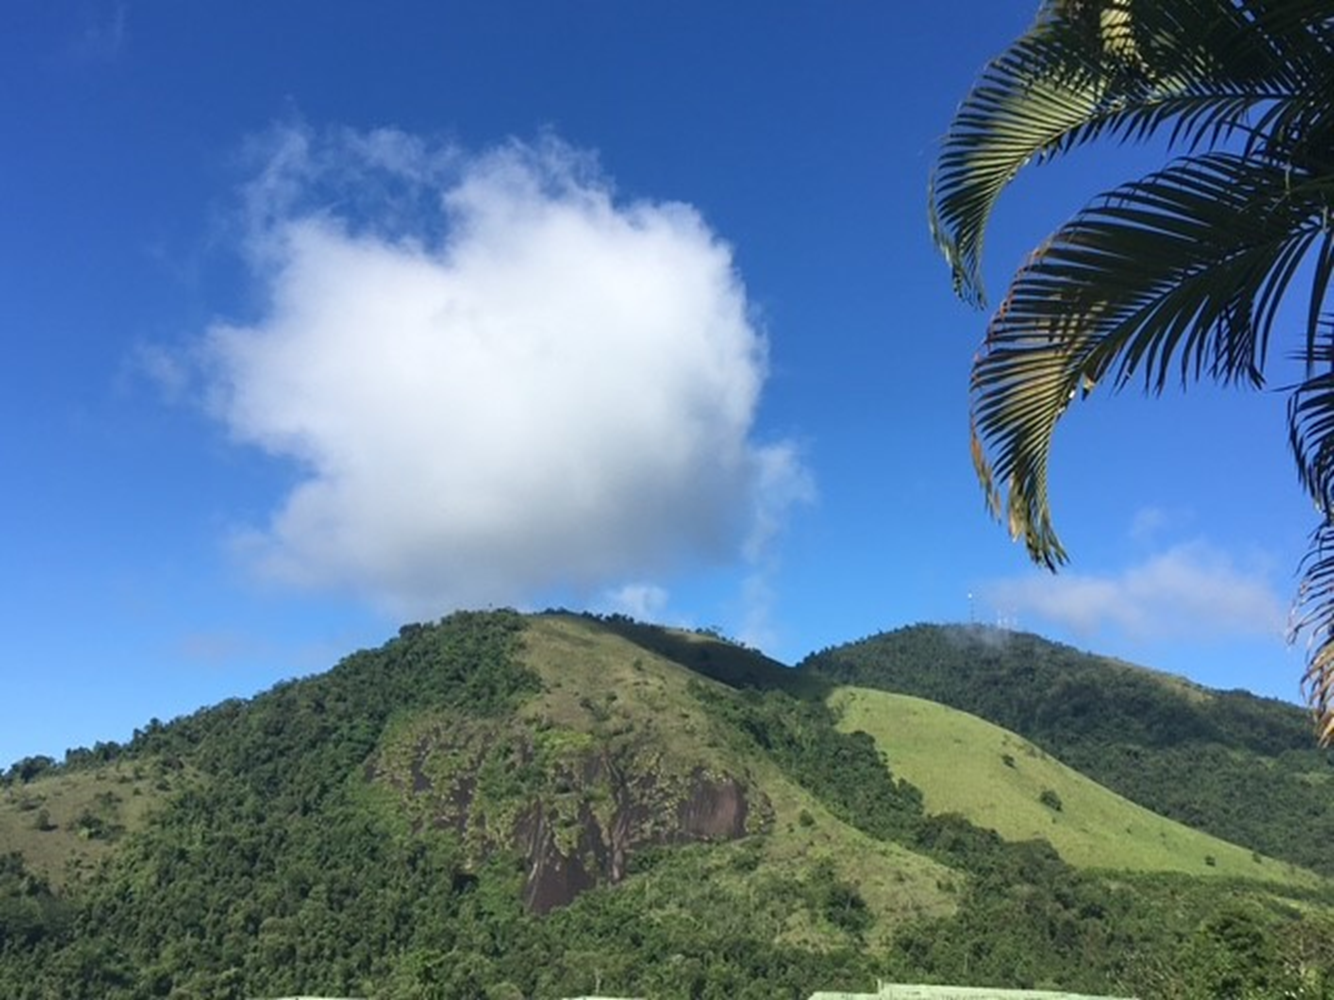

**Solution:**

CheckAnswer("Exercise3","Select") % Non-default options include: "Histogram", "K-Means Clustering" and "Graph-Cut"

## Glossary

**k-means clustering**: an algorithm used to partition data into k*k* distinct clusters, where k*k* is a user-defined number. It aims to find centroids that represent different groups within the data. ↑ Return to Text

**graph-cut segmentation**: an algorithm that represents an image as a graph, with pixels as nodes and edges connecting them. Edges may have weights indicating pixel similarity. The goal is to partition the graph into segments by cutting edges, grouping similar pixels, and classifying them into foreground and background regions. ↑ Return to Text

**histogram-based segmentation**: a technique that segments an image by analyzing pixel intensity histograms and identifying thresholds to separate regions.  ↑ Return to Text

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option) % Function to check answers for exercises
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1", struct("answer","[100,150]","hint","Which pixel intensity correlates with gray?"),...
    "Exercise2", struct("answer","Three","hint","Which cluster has the greatest mean silhouette value?"),...
    "Exercise3", struct("answer","Graph-Cut","hint","Which technique is best for isolating specific objects?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.")
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        warning("%s",hint)
    end
else
    warning("Exercise not found.")
end
end

function [PixSamp,idx] = PlotKClust(ImageR,k,Preview) % Function to perform k-means clustering and plot results in a scatter plot
if Preview
    figure
    imshow(ImageR)
    title("Original Image")
end
% Convert image to Lab color space
ImageR = imread(ImageR);
ImageRL = rgb2lab(ImageR);

% Convert to double precision for processing
ImageRDouble = im2double(ImageRL);

% Get image dimensions
[X,Y,Z] = size(ImageRDouble);

% Reshape the image into an (X*Y) × 3 matrix (each row is a pixel, each column is a color channel)
pixels = reshape(ImageRDouble,X*Y,Z);

% Downsample pixels if necessary
MaxSamp = 10000; % Set a limit on how many pixels to use for silhouette
NumPix = size(pixels,1);
if NumPix > MaxSamp
    RandIdx = randperm(NumPix,MaxSamp); % Randomly select samples
    PixSamp = pixels(RandIdx,:);
else
    PixSamp = pixels;
end

% Run K-means clustering
[idx,centroids] = kmeans(PixSamp,k,Replicates=3);

% Plot K-means clusters in a 2D scatter plot
figure
gscatter(PixSamp(:,2),PixSamp(:,3),idx)
hold on

% Plot centroids of the clusters
scatter(centroids(:,2),centroids(:,3),100,"k","x",LineWidth=2)

% Set labels and title for the 2D plot
xlabel("a* Channel")
ylabel("b* Channel")
title("Scatter Plot of Clusters and Centroids")

% Create legend entries for each cluster and centroids
legendEntries = cell(k + 1,1);
for i = 1:k
    legendEntries{i} = "Cluster " + num2str(i);
end
legendEntries{k + 1} = "Centroids";
legend(legendEntries,Location="bestoutside")
hold off
end

function DispHist(Range,ToyG) % Function to display histogram
if ~strcmp(Range,"Select")
    Range = str2num(Range); %#ok<*ST2NM>
    histogram(ToyG,BinLimits=Range)
    xlabel("Pixel Intensity")
    ylabel("Counts")
    axis padded
    ax = gca;
    ax.PositionConstraint = "outerposition";
    xlim(Range); % Zoom in on the intensity selected range
    if strcmp(Range,"White Pixels")
        yticks(0:2000:8000)
        ylim([0 8000]); % Keep y-axis limits the same
    else
        ylim auto
        yticks auto
    end

else
    warning("Select a valid option.")
end
end

function HistDisp(Image) % Function to display a histogram with a grayscale colorbar
histogram(Image)
xlabel("Intensity Range")
ylabel("Counts")
axis padded
ax = gca;
ax.PositionConstraint = "outerposition";
colormap("gray")
colorbar(ax,Ticks=[0 0.5 1],TickLabels=["Black" "Gray" "White"],Location="southoutside")

end

function [clusterIndices,score] = ScatKmeans(ImgDouble,K)
[clusterIndices,~] = kmeans(ImgDouble,K,Replicates=10);

% Display results

[~,score] = pca(ImgDouble);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end

hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"x",LineWidth=2);
hold off
h.DisplayName = "Centroids";
legend
title("K-Means Clustered Data");
xlabel("First principal component")
ylabel("Second principal component")
end

function [x,y,G,Edges] = GrphCut(GrphImg)

[ImgHeight,ImageWidth,~] = size(GrphImg); % Get the size of the image

figure
imshow(GrphImg); % Display the image
hold on % Keep the image while plotting the graph

% Define the number of rows and columns for the grid
rows = 3;
cols = 3;

% Compute the center of the image
ImgCtrX = ImageWidth/2;
ImgCtrY = ImgHeight/2;

% Compute the center of the grid
GrdCtrX = (cols - 1)*100/2;
GrdCtrY = (rows - 1)*100/2;

% Offset to align the middle node with the image center
XOffset = ImgCtrX - GrdCtrX;
YOffset = ImgCtrY - GrdCtrY;

% Calculate node positions and center the grid
[x,y] = meshgrid(linspace(0,(cols - 1)*100,cols) + XOffset, ...
    linspace(0,(rows - 1)*100,rows) + YOffset);

% Flatten the grid for easier handling
x = x(:);
y = y(:);

A = ones(9) - eye(9); % Create an adjacency matrix for a complete graph on 9 vertices
G = graph(A);
Edges = G.Edges.EndNodes;
end